syms t
x=exp(-t)

$$x = {\mathrm{e}}^{-t}$$

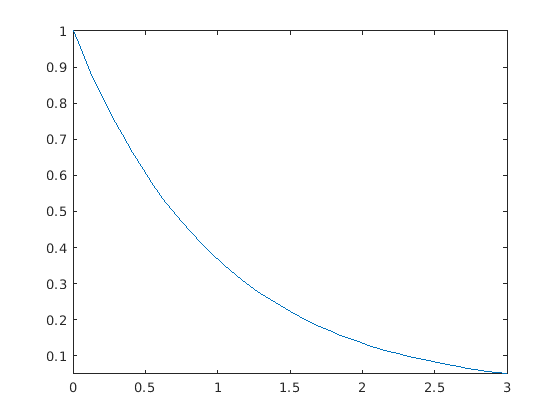

t0=0;
t1=3;
%Cantidades necesarias para
%series de Fourier
T0=t1-t0;
w0=2*pi/T0;

%Ver funcion
fplot(x,[t0 t1])

## Potencia del intervalo

False= Fracción; True= En decimal o punto flotante

%Potencia del intervalo
P=(1/T0)*int(x^2,t0,t1)

$$P = \frac{1}{6}-\frac{{\mathrm{e}}^{-6}}{6}$$

P=double(P)

P = 0.1663


%Integral de exponenciales complejas
%int() es para hacer integrales simbolicas
%integral() es para hacer integrales numericas
k=3;
ee=exp(-1i*k*w0*t)

$$ee = {\mathrm{e}}^{-2\,\pi \,t\,\mathrm{i}}$$

a_tmp=(1/T0)*int(x*ee,t0,t1)

$$a\_tmp = -\frac{{\mathrm{e}}^{-3}\,\left({\mathrm{e}}^{3}-1\right)\,\mathrm{i}}{3\,\left(2\,\pi -\mathrm{i}\right)}$$

a_tmp=double(a_tmp)

a_tmp = 0.0078 - 0.0492i


%Generalizar con un ciclo for
%Integral para distintos valores de k
%a_k sea un vector de numeros double
%-3 a 3
N=10;
k=-N:N;
%Ticket: Agregar eso porfa
%[ee,a]=fcc(x,t0,T0,N,'Verbose',false);
[ee,a]=fcc(x,t0,T0,N);

Coeficiente k=-10 
Coeficiente k=-9 
Coeficiente k=-8 
Coeficiente k=-7 
Coeficiente k=-6 
Coeficiente k=-5 
Coeficiente k=-4 
Coeficiente k=-3 
Coeficiente k=-2 
Coeficiente k=-1 
Coeficiente k=0 
Coeficiente k=1 
Coeficiente k=2 
Coeficiente k=3 
Coeficiente k=4 
Coeficiente k=5 
Coeficiente k=6 
Coeficiente k=7 
Coeficiente k=8 
Coeficiente k=9 
Coeficiente k=10 


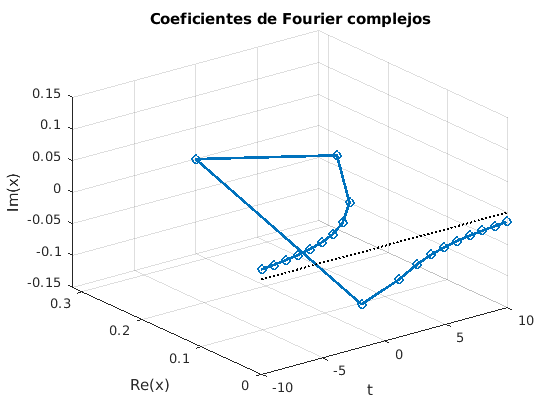

%Visualizar coeficientes
%Complejo 3d
figure
complex3Dplot(k,a)
title("Coeficientes de Fourier complejos")

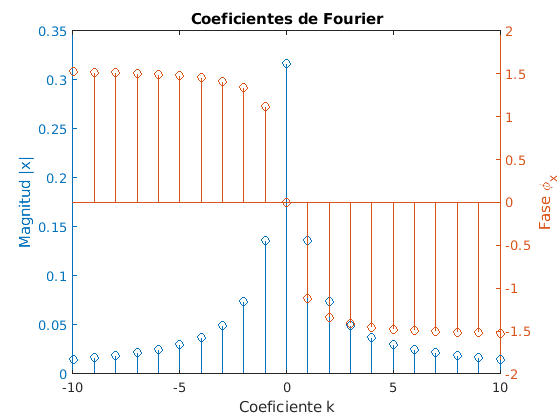


%Magnitud y fase
figure
yyaxis left
stem(k,abs(a))
ylabel("Magnitud |x|")
yyaxis right
stem(k,angle(a))
ylabel("Fase \phi_x")
xlabel("Coeficiente k")
title("Coeficientes de Fourier")

## Parseval

P_a=sum(abs(a).^2)

P_a = 0.1619

%Cantidad de potencia que tienen
%Los coeficientes de fourier respecto
%a la potencia de la señal original
eta=P_a/P

eta = 0.9738

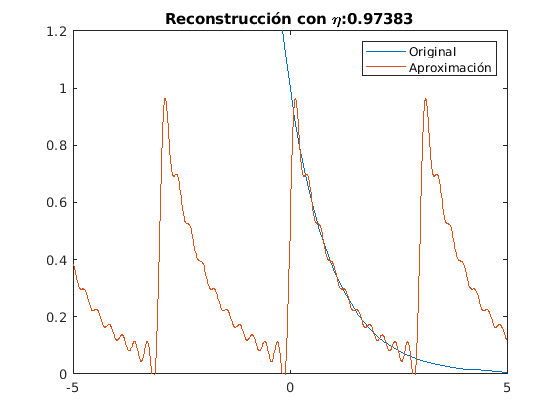


%Reconstrucción con series de fourier
figure
fplot(x)
hold on
fplot(sum(a.*ee))
hold off
legend("Original","Aproximación")
title("Reconstrucción con \eta:"+eta)
ylim([0 1.2])

## Aproximar función compleja